clear;
f = 10e9;
omega = 2*pi*f;
ep1 = 1;
ep2 = 10 - 1i*18;
mu0 = 4*pi*1e-7;
ep0 = 8.854e-12;
k1 = omega*sqrt(mu0*ep0*ep1);
k2 = omega*sqrt(mu0*ep0*ep2);
a = 2*k1;

kz1 = @(kp) sqrt(k1 ^2 - kp .^2);
kz2 = @(kp) sqrt(k1 ^2 * ep2 - kp .^2);

gamma_1h = @(kp) -(kz2(kp) - kz1(kp)) ./ (kz2(kp) + kz1(kp));
gamma_1e = @(kp) (kz2(kp) / ep2 - kz1(kp)) ./ (kz2(kp) / ep2 + kz1(kp));

G_1 = @(kp) k1 * (gamma_1h(kp)) ./ (1i * kz1(kp));
G_2 = @(kp) k1 .* (gamma_1e(kp) - gamma_1h(kp)) ./ kp;

kp = linspace(-5,5,1e5);
% g1 = G_1(kp);
% g2 = G_2(kp);
% % plot(kp,real(g1))
% % hold on
% plot(kp,real(g2))
S_0 = @(kp) G_1(kp) .* besselj(0, kp * 1e1) .* kp;
S_1 = @(kp) G_2(kp) .* besselj(1, kp * 1e1) .* kp;
J_0 = @(kp) besselj(0, 1e0*kp);
J_1 = @(kp) besselj(1, 1e0*kp);
% 

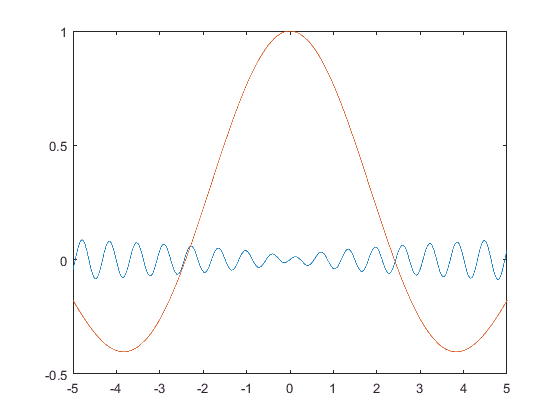

close all
plot(kp, real(S_0(kp)));
hold on
plot(kp, J_0(kp));

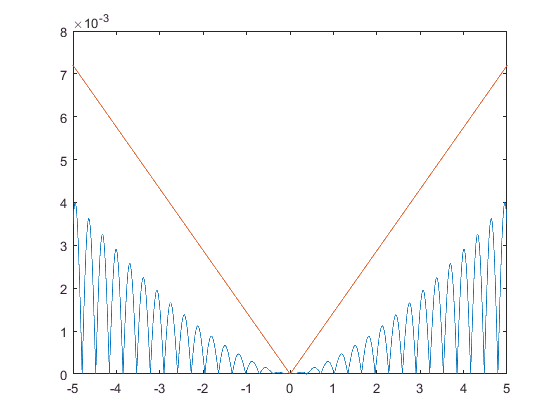

close all
plot(kp, abs(S_1(kp)));
hold on
plot(kp, abs(G_2(kp)));


yy0 = AllZeros(J_0, a, 1.5*a)

yy0 =   420.1883  423.3299  426.4715  429.6131  432.7547  435.8963  439.0379  442.1795  445.3210  448.4627  451.6042  454.7459  457.8874  461.0291  464.1706  467.3123  470.4538  473.5955  476.7369  479.8787  483.0201  486.1619  489.3033  492.4451  495.5865  498.7283  501.8697  505.0115  508.1528  511.2947  514.4360  517.5779  520.7192  523.8612  527.0024  530.1444  533.2856  536.4276  539.5687  542.7108  545.8519  548.9940  552.1351  555.2773  558.4183  561.5605  564.7015  567.8437  570.9846  574.1270


yy1 = AllZeros(J_1, a, 1.5*a)

yy1 =   421.7579  424.8995  428.0411  431.1827  434.3243  437.4659  440.6075  443.7491  446.8907  450.0323  453.1739  456.3155  459.4571  462.5987  465.7403  468.8819  472.0235  475.1651  478.3067  481.4483  484.5899  487.7315  490.8731  494.0147  497.1563  500.2979  503.4395  506.5811  509.7227  512.8643  516.0059  519.1475  522.2891  525.4307  528.5723  531.7139  534.8554  537.9970  541.1386  544.2802  547.4218  550.5634  553.7050  556.8466  559.9882  563.1298  566.2714  569.4130  572.5546  575.6962


First_15_zeros_J0 = yy0';
First_15_zeros_J1 = yy1';
save besselzeros.mat